%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

MTOW = 133887

MTOW = 133887

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = MTOW*0.946

W = 1.2666e+05

WingLoad = 93.55

WingLoad = 93.5500


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.10

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = MTOW/WingLoad %ft^2

S = 1.4312e+03

b = 118;
AR = b^2/S

AR = 9.7290

%AR2 = 5.23
%b2=100
TaperRatio = 0.4;
b = 118

b = 118

Q = 1.01

Q = 1.0100

SweepQuartC = 0;

%Fuselage Parameters
Df = 15.5; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 0.0399

e = 1/(K*AR*pi)

e = 0.8204


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 17.3266

Cmac = 12.8712

Ymac = 25.2857

SweepMaxT = -1.5140

Sexp = 1.1732e+03

Re = 7.1669e+07

SweepMaxT = -1.5140

Cf = 0.0022

FF = 1.7036

Swet = 2.4109e+03

CDo = 0.0063


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

Cf = 0.0023

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0023


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

Cf = 0.0023

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0017


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

Cf = 0.0018

FF = 1.2582

SWet = 4.0346e+03

CDo = 0.0064

CDoFuse = 0.0064


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

Re = 2.1442e+07

Cf = 0.0024

FF = 1.1526

SWet = 57.8577

CDo = 1.7080e-04

CDoNacelle = 0.0014


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S)

Re = 5.2779e+07

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.5711e-04

CDoBlisters = 3.5711e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0046


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0018


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 8.9212e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0254





CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.3933

LDMax = 0.7862

LDMax = 1.1783

LDMax = 1.5694

LDMax = 1.9590

LDMax = 2.3468

LDMax = 2.7323

LDMax = 3.1154

LDMax = 3.4956

LDMax = 3.8726

LDMax = 4.2461

LDMax = 4.6158

LDMax = 4.9813

LDMax = 5.3424

LDMax = 5.6989

LDMax = 6.0504

LDMax = 6.3967

LDMax = 6.7376

LDMax = 7.0729

LDMax = 7.4023

LDMax = 7.7256

LDMax = 8.0428

LDMax = 8.3535

LDMax = 8.6578

LDMax = 8.9554

LDMax = 9.2463

LDMax = 9.5303

LDMax = 9.8073

LDMax = 10.0773

LDMax = 10.3403

LDMax = 10.5961

LDMax = 10.8448

LDMax = 11.0863

LDMax = 11.3206

LDMax = 11.5478

LDMax = 11.7678

LDMax = 11.9807

LDMax = 12.1865

LDMax = 12.3852

LDMax = 12.5769

LDMax = 12.7617

LDMax = 12.9397

LDMax = 13.1109

LDMax = 13.2753

LDMax = 13.4332

LDMax = 13.5845

LDMax = 13.7295

LDMax = 13.8681

LDMax = 14.0006

LDMax = 14.1269

LDMax = 14.2473

LDMax = 14.3619

LDMax = 14.4707

LDMax = 14.5740

LDMax = 14.6717

LDMax = 14.7642

LDMax = 14.8514

LDMax = 14.9335

LDMax = 15.0106

LDMax = 15.0829

LDMax = 15.1505

LDMax = 15.2136

LDMax = 15.2721

LDMax = 15.3264

LDMax = 15.3764

LDMax = 15.4224

LDMax = 15.4644

LDMax = 15.5026

LDMax = 15.5370

LDMax = 15.5679

LDMax = 15.5953

LDMax = 15.6193

LDMax = 15.6400

LDMax = 15.6576

LDMax = 15.6722

LDMax = 15.6838

LDMax = 15.6925

LDMax = 15.6986

LDMax = 15.7020

LDMax = 15.7028

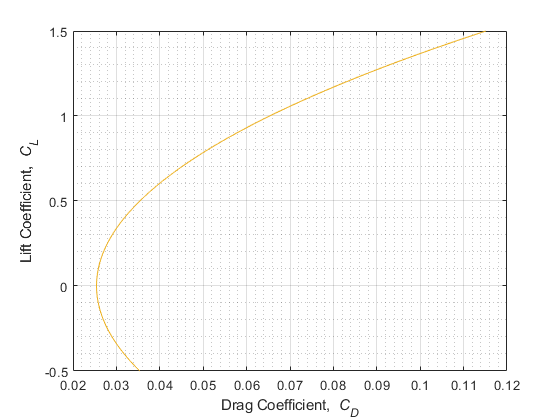


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor

LDMax

LDMax = 15.7028


DynViscSL = 3.737*10^(-7)

DynViscSL = 3.7370e-07

Swf = 1100

Swf = 1100

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%
% 
% [CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);
% 
% [CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);
% 
% CDoHtSL = CDoHtSL*Sh/S
% 
% [CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);
% 
% CDoVtSL = CDoVtSL*Sv/S/2
% 
% [CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S)
% 
% [CDoNacelleSL] = 8*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S)
% 
% [CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S)
% 
% CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber
% 
% k1 = 1.75
% 
% k2Landing = 0.0375
% 
% k2TO = 0.0125
% 
% dCDoLanding = k1*k2Landing*Swf/S
% 
% dCDoTO = k1*k2TO*Swf/S
% 
% for x=1:201
%     
%    CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;
% 
%    CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
%     
% end
% 
% 
% 
% plot (CDLanding,CL)
% plot (CDTO,CL)
% 
% legend('Cruise','Landing', 'Takeoff')
% legend('Location','southeast')
% 
% hold off
